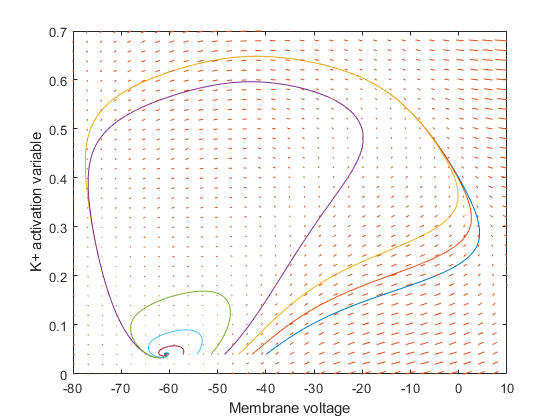

dt = 0.001;
time = 100;
loop  = ceil(time/dt);
t = (1:loop)*dt;

I=0;
gl=8;
gNa=20; 
gK=10;

curve=8;
v=zeros(loop,curve);
n=zeros(loop,curve);
v(1,:)=linspace(-40,-60,curve);
n(1,:)=ones(1,curve)*0.04;

for j=1:curve
    for i=1:loop-1
        v(i+1,j) = v(i,j)+dt*(I-gNa.*infi(v(i,j),-20,15).*(v(i,j)-60) ...
            -gl.*(v(i,j)+78)-gK.*n(i,j).*(v(i,j)+90));
        n(i+1,j) = n(i,j)+dt*(infi(v(i,j),-45,5)-n(i,j));
    end
end

% 画轨迹图
figure
for i=1:curve
    plot(v(:,i),n(:,i))
    hold on
end

% 画向量场
[x,y] = meshgrid(-80:3:10,0:0.02:0.7);
u=I-gNa.*infi(x,-20,15).*(x-60)-gl.*(x+78)-gK.*y.*(x+90);
n=infi(x,-45,5)-y;
vec = quiver(x,y,u,n,'MaxHeadSize',0.0001);
set(gca, 'XLim',[-80 10],'YLim',[0 0.7]);
xlabel('Membrane voltage');
ylabel('K+ activation variable');

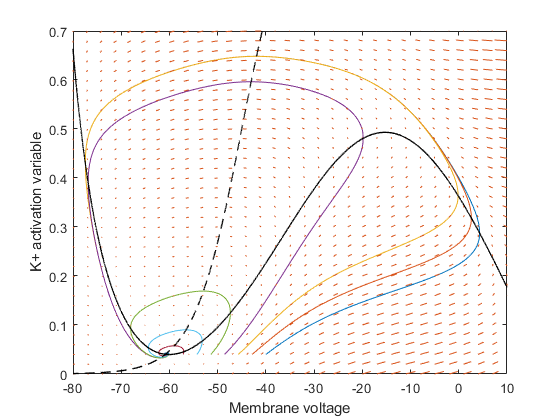

% 画等高线
[xn,yn] = meshgrid(-80:0.1:10,0:0.0001:0.7);
un=I-gNa.*infi(xn,-20,15).*(xn-60)-gl.*(xn+78)-gK.*yn.*(xn+90);
nn=infi(xn,-45,5)-yn;
hold on
contour(xn,yn,un,'LevelList',0,'LineWidth',1,'LineColor',"black");
contour(xn,yn,nn,'LevelList',0,'LineWidth',1,'LineColor',"black","LineStyle","--");

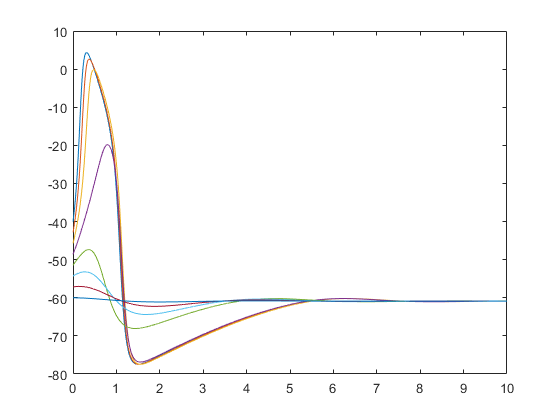

% 画V-t图象
figure
plot(t,v)
set(gca,'XLim',[0 10]);